# Test concept: Drop tracking algorithm

**Aim: **Initial script to test concept for drop tracking. 

Code developed using model video (also used in initial development of video-processing workflow): **SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi**

**Log:**

**30-Jan; SWC.** Started code. Tested data tabulation for 1 frame.

**31-Jan; SWC.** Added code to tabulate data for all drops in all frames. 

**1-Feb; SWC. **Added comments to script. Full data table exported and labelled manually, so can use to test drop mapping algorithm before combining with ML model. data table which can be queried contains: 1) frame #, 2) drop #, 3) centroid x-coordinate, 4) drop class state.

**3-Feb; SWC. **

clear all 
close all 
clc 

**Background information**

So far, we have scripts to: 

- Read a video and extract individual frames; 

- Perform image processing on each extracted frame and obtain information on drops (drop area, centroid coordinates, bounding box coordinates). 

A complete script (d*ropCropMULTI.m*) has also been written such that bounding box coordinates are used to crop and save individual drop images.

**Next steps**

Following detection of drops (region of interests) in each frame, we need to assign a class label for each drop - using the machine learning classification model. 

2 ways we can approach this: 

- save each drop image in a temporary subfolder, then process all the images from all frames as ONE big batch. A table containing the entries for frame number, drop number and centroid x-coordinates would have been generated earlier during the process when cropped images were saved. Thus, output (drop class predictions) from machine learning model can directly be appended to the data table as an additional column (drop class). 

- instead of saving cropped images as new files, maybe we can pass it directly to the machine learning model as part of the for loop? Though, this means the machine learning classification step will have to be performed MULTIPLE times for a given video. There is a compromise between computing time to save images as .jpg versus running the ML model multiple times.

*(still undecided which is better, need to run some tests...)*

## 1) Load video

vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; %<-------- user-defined input!!
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 1434

## 2) Background generation 

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 1.683934 seconds.


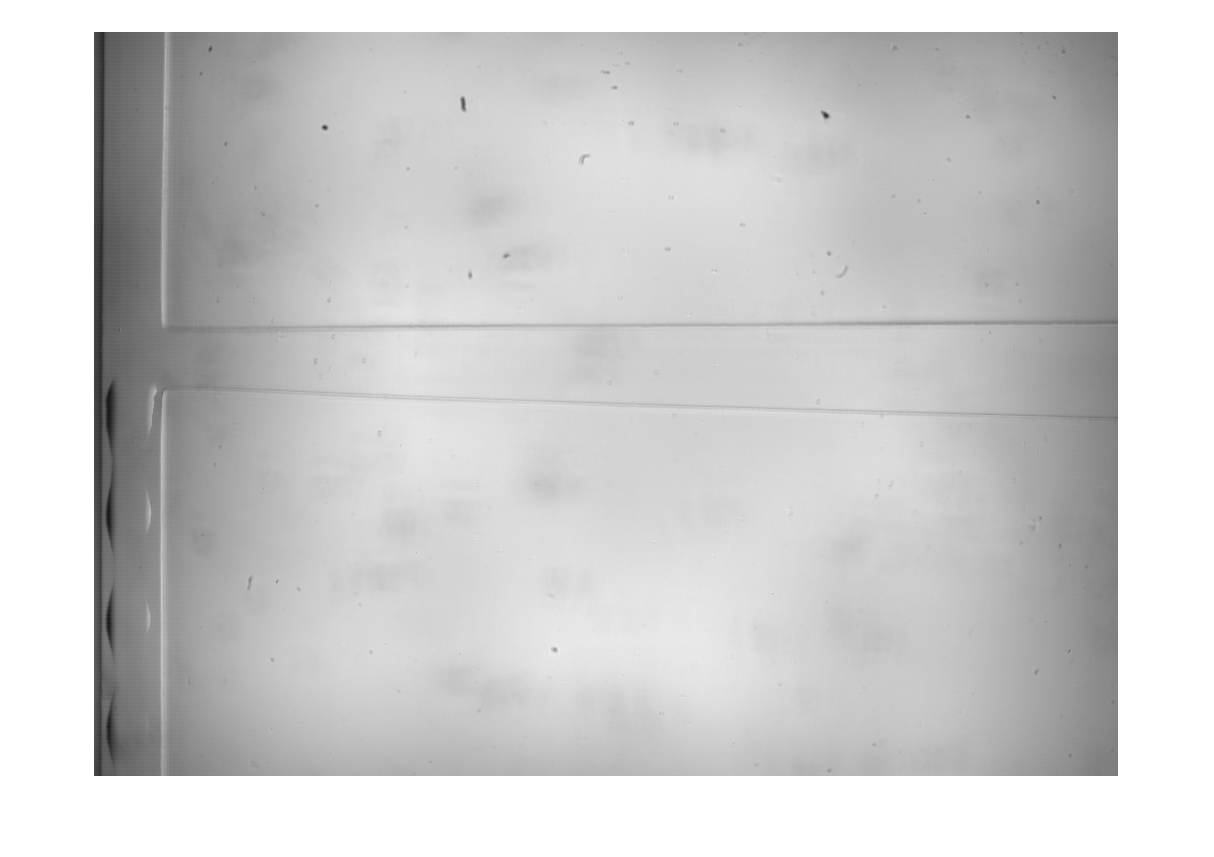


figure; imshow(med_pix);

## **3a) Generation of data table for drop tracking across frames - INITIAL TEST (ON SINGLE FRAME)**

Note: can run this if interested/ for debugging, but make sure '1.jpg' is in same folder as script.

% headers = {'Frame#' 'Drop#' 'Centroid' 'Class'};
% varTypes = {'double' 'double' 'double' 'double'};
% 
% Ttest = table('Size',[0 4],'VariableTypes',varTypes,'VariableNames',headers)
% 
% Itest = imread('1.jpg'); 
% imshow(Itest)

% % background subtraction
% subtest = med_pix - Itest; 
% % binarise image
% bintest = imbinarize(subtest, 0.2); 
% % morphological fill
% filltest = bwconvhull(bintest,'objects');
% % remove noise objects
% cfilltest = bwareaopen(filltest, 1800);
% % detect area of interest
% roitest = regionprops('table',cfilltest);
% % remove objects outside of main flow channel
% roitest(roitest.Centroid(:,1) < 140, :) = []

% frameNumtest    = 1111*ones(height(roitest),1);
% dropNumtest     =  [1:height(roitest)]';
% centroidtest = roitest.Centroid(:,1);
% classtest = [1 1 1 1 1 1 1 3]'; % random numbers just so to complete the
% table 
% 
% datatest = table(frameNumtest, dropNumtest, centroidtest, classtest, 'VariableNames', headers)
% Ttest = vertcat(Ttest,datatest)


## **3b) Generation of data table for drop tracking across frames -  PROCESS FULL VIDEO (ALL EXTRACTED VIDEO FRAMES)**

Note: In practice, should combine this with video frame extraction function (*extractVidFrames.m)* to generate a subfolder cotaining all the frames which the current script can act on. 

Here, the frames have already been extract and saved under 'extractedFrames_1' folder - make sure this is present before running the code!

% access frames
frames_folder = dir('extractedFrames_1\*.jpg'); %<--- make sure extractedFrames_1 folder is in directory!

% prepare empty table
headers = {'Frame#' 'Drop#' 'Centroid' 'Class'}; % column names: frame number, drop number, centroid x-coord, drop class state
varTypes = {'double' 'double' 'double' 'double'}; % formalities - need to tell MATLAB what the expected data class type would be. All numbers (doubles) in this case

T = table('Size',[0 4],'VariableTypes',varTypes,'VariableNames',headers)


T =

  0×4 empty table



tic
% loop through each frame in folder 
for i = 1:numel(frames_folder)
    
    % get image file name
    filename = fullfile('extractedFrames_1', sprintf('%d.jpg',i));
    % read image
    img = imread(filename);
%     figure; imshow(img)
    
    % background subtraction
    sub = med_pix - img; 
    % binarise image
    bin = imbinarize(sub, 0.2); 
    % morphological fill
    fill = bwconvhull(bin,'objects');
    % remove noise objects (anything <1800 pix^2)
    cfill = bwareaopen(fill, 1800);
    % detect area of interest
    roi = regionprops('table',cfill);
    % remove objects outside of main flow channel
    roi(roi.Centroid(:,1) < 140, :) = [];
    
    % collect data for table
    data = table(i*ones(height(roi),1),...
        [1:height(roi)]',...
        roi.Centroid(:,1),...
        randi(3, height(roi),1), ... % this data should come from ML classification prediction, but for now, just random numbers to complete table
        'VariableNames', headers);
    
    % add data to table
    T = vertcat(T,data);
    
end
toc

Elapsed time is 109.023328 seconds.



% show final data table
T

T = 9388×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

      1         1       241.22       3  
      1         2        316.3       3  
      1         3       510.61       1  
      1         4       663.86       3  
      1         5        734.4       2  
      1         6       824.03       1  
      1         7       899.29       1  
      1         8       998.05       2  
      2         1       241.84       3  
      2         2       316.78       3  
      2         3       511.07       1  
      2         4       664.19       3  
      2         5       734.88       3  
      2         6       824.47       2  
      2         7       899.54       3  
      2         8       998.26       1  


% % save table to excel 
% writetable(T, 'test001_datatable.xlsx')

The final table is what I hope would be sufficient to perform database query and compute coalescence time.

Here's the correctly labelled table:

acT = readtable('test001_datatable_labelled.xlsx',"VariableNamingRule","preserve")

acT = 9388×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

      1         1       241.22       1  
      1         2        316.3       1  
      1         3       510.61       1  
      1         4       663.86       1  
      1         5        734.4       1  
      1         6       824.03       1  
      1         7       899.29       1  
      1         8       998.05       1  
      2         1       241.84       1  
      2         2       316.78       1  
      2         3       511.07       1  
      2         4       664.19       1  
      2         5       734.88       1  
      2         6       824.47       1  
      2         7       899.54       1  
      2         8       998.26       1  
